Anant Mital 

Student # 272484

## Problem 2

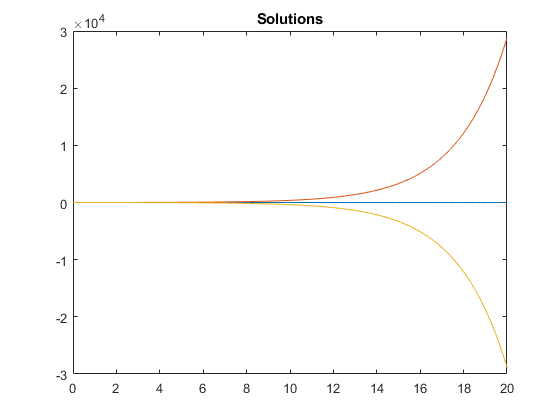

syms y(t);
% taking t = [0,20] as t = [0,400] is taking too much time for output
f = @(t, y, a, b, c) [-y(2)-y(3); y(1)+a*y(2); b+y(2)*(y(1)-c) ];
[t2, y2] = ode45(@(t,y) f(t, y, 0.432, 2, 4), [0, 20], [1;1;1]);

figure;
plot(t2,y2);
title('Solutions');

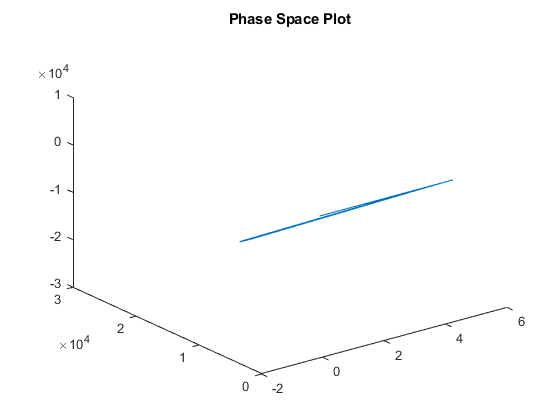


figure;
plot3(y2(:,1), y2(:,2), y2(:,3));
title('Phase Space Plot');

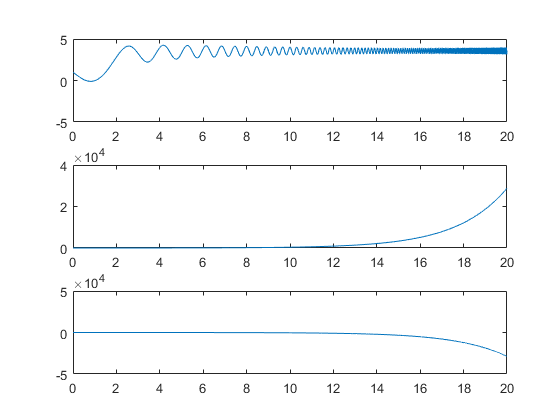


figure;
subplot(3,1,1);
plot(t2,y2(:,1));

subplot(3,1,2);
plot(t2,y2(:,2));

subplot(3,1,3);
plot(t2,y2(:,3));